clc
clear
close all

% Model of the system (Plant)
G = tf(1,[1/3,0.1,-2.455])

G =
 
              1
  --------------------------
  0.3333 s^2 + 0.1 s - 2.455
 
Continuous-time transfer function.



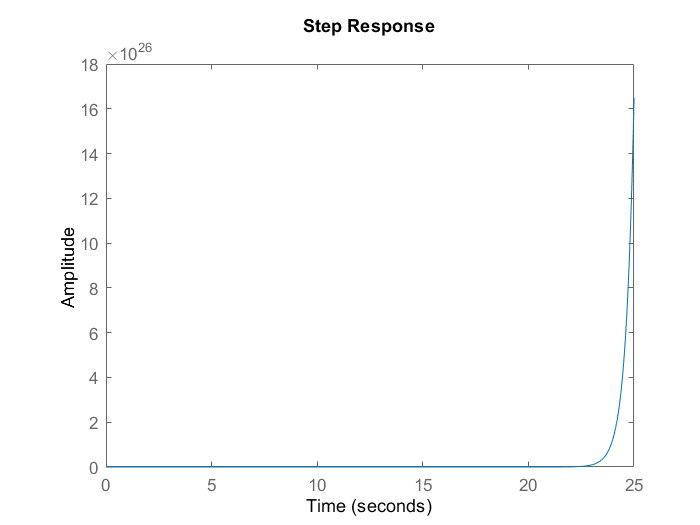

step(G);

poler = pole(G)

poler =    -2.8680
    2.5680


% Create a P-Controller
G = tf(1,[1/3,0.1,-2.455])

G =
 
              1
  --------------------------
  0.3333 s^2 + 0.1 s - 2.455
 
Continuous-time transfer function.




Kp = 100;
C = pid(Kp)

C =
 
  Kp = 1
 
P-only controller.




H = G*C

H =
 
              1
  --------------------------
  0.3333 s^2 + 0.1 s - 2.455
 
Continuous-time transfer function.



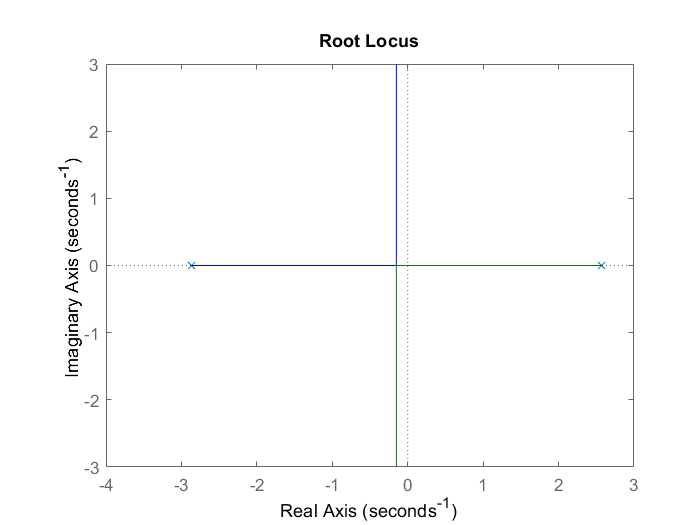

rlocus(H)

% Create a PI-Controller
clear
G = tf(1,[1/3,0.1,-2.455])

G =
 
              1
  --------------------------
  0.3333 s^2 + 0.1 s - 2.455
 
Continuous-time transfer function.



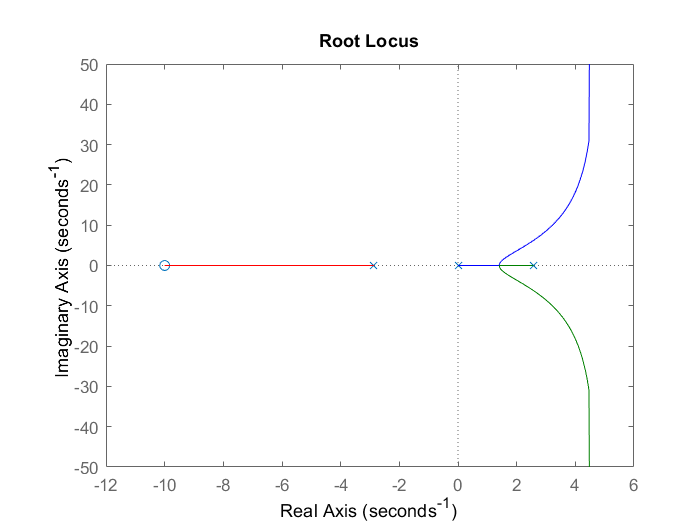


Kp = 1;
Ki = 10;
C = pid(Kp,Ki);

H = G*C;
rlocus(H)

% Create a PI-Controller without pid()
clear

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G = 1 / (1/3*s^2 + 0.1*s -2.455)

G =
 
              1
  --------------------------
  0.3333 s^2 + 0.1 s - 2.455
 
Continuous-time transfer function.




Kp = 1;
Ki = 1;
zi = -1;            % Specificer nulpunkt
%C = Kp + Ki/s
%C = Kp*(s+Ki/Kp)/s  % Omskrevet
C = Kp*(s-zi)/s     % zi = -Ki/Kp

C =
 
  s + 1
  -----
    s
 
Continuous-time transfer function.




H = G*C

H =
 
              s + 1
  ------------------------------
  0.3333 s^3 + 0.1 s^2 - 2.455 s
 
Continuous-time transfer function.



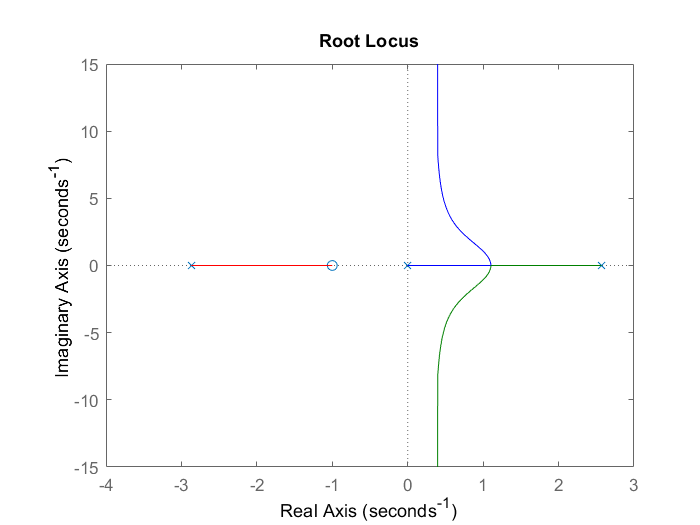

rlocus(H)

% Create a PD-Controller
clear

%G = 1 / (1/3*s^2 + 0.1*s -2.455)
G = tf(1,[1/3,0.1,-2.455])

G =
 
              1
  --------------------------
  0.3333 s^2 + 0.1 s - 2.455
 
Continuous-time transfer function.




s = tf('s');

Kp = 1;
Ti = 0;
Td = 1/7;
C = Kp*(Td*s^2 + s)/s

C =
 
  0.1429 s^2 + s
  --------------
        s
 
Continuous-time transfer function.



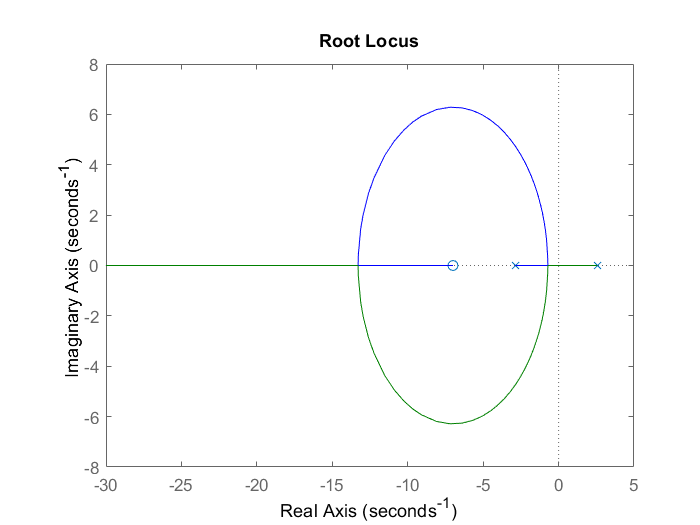

H = C*G;
rlocus(H)

% % PID Controller skabelon
% C = Kp + Ki*1/s + Kd*s;         % "Standard" form
% C = Kp*(1 + 1/(Ti*s) + Td*s);   % Omskrivninger:
% C = Kp*(Td*s^2 + s + 1/Ti)/s;   % Td = 0 for PI-controller. Fjern 1/Ti for PD-controller

% % PID Controller
% clear
% 
% G = tf(1,[1/3,0.1,-2.455]);
% 
% s = tf('s');
% Kp = 30; Ti = 1; Td = 1/7;
% C = Kp*(1 + 1/(Ti*s) + Td*s)
% 
% H = C*G;
% rlocus(H)